# Demo 5 - Pseudotime Analysis and Gene Network Functions

## Load example data set, X

cdgea; % set working directory
[X,genelist]=sc_readfile('example_data/GSM3044891_GeneExp.UMIs.10X1.txt');

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


## Select genes with at least 3 cells having more than 5 reads per cell.

[X,genelist]=sc_selectg(X,genelist,5,3);

## Trajectory analysis using the PHATE+splinefit method

s=run_phate(X,3,true); [t,xyz1]=i_pseudotime_by_splinefit(s,1); hold on plot3(xyz1(:,1),xyz1(:,2),xyz1(:,3),'-r','linewidth',2);

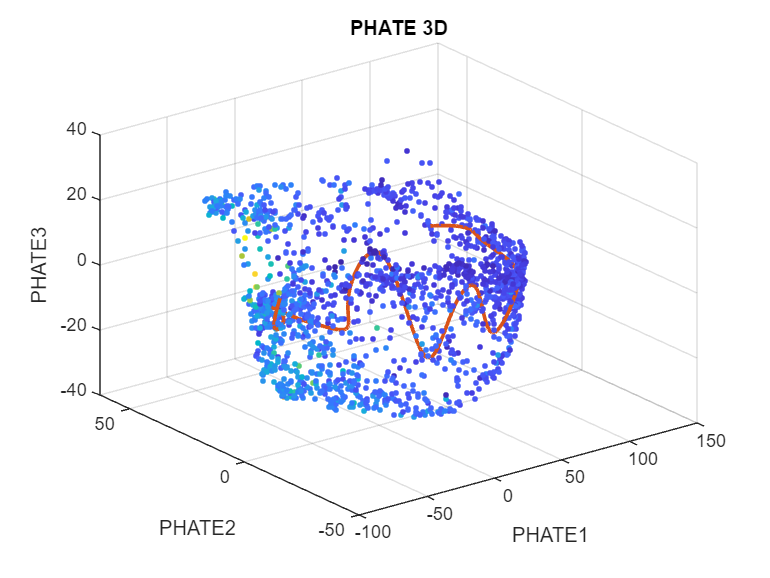

Doing PCA
PCA took 0.36728 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 1567
First iteration: k = 200
Number of samples below the threshold from 1st iter: 1565
Using radius based search for the rest
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.060017 seconds
Make kernel row stochastic
Running PHATE without landmarking
Diffusing operator
Diffusion took 2.455 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.1727 seconds
Doing classical MDS
CMDS took 0.026429 seconds
Doing metric MDS:
MMDS took 30.5587 seconds
Done.
Total time 33.6401 seconds


% Calculte pseudotime T
figure;
t=sc_trajectory(X,"type","splinefit","plotit",true);

## Plot gene expression profile of cells ordered according to their pseudotime T.

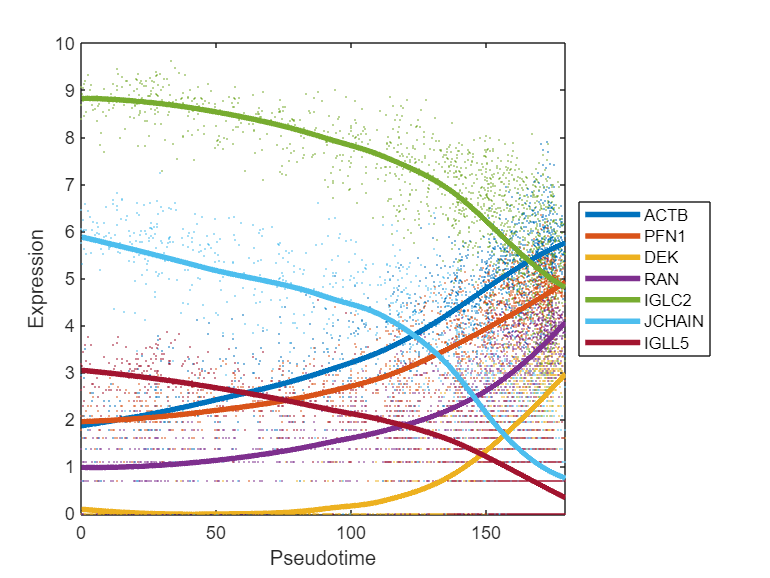

r=corr(t,X','type','spearman'); % Calculate linear correlation between gene expression profile and T
[~,idxp]= maxk(r,4);  % Select top 4 positively correlated genes
[~,idxn]= mink(r,3);  % Select top 3 negatively correlated genes
selectedg=genelist([idxp idxn]);

% Plot expression profile of the 5 selected genes
try
    figure;
    pkg.i_plot_pseudotimeseries(log1p(X),genelist,t,selectedg)
catch
end

% % Nonlinear correlation  
%
% r=zeros(size(X,1),1);
% for k=1:size(X,1)
%     k
%     r(k)=distcorr(t,double(X(k,:))');
% end
% [~,idxp]= maxk(r,3);
% [~,idxn]= mink(r,2);
% selectedg=genelist([idxp; idxn]);
% figure;
% pkg.i_plot_pseudotimeseries(log1p(X),genelist,t,selectedg)

## Trajectory analysis using TSCAN

Calculte pseudotime T

try
figure;
t=sc_trajectory(X,"type","tscan","plotit",true);

r=corr(t,X','type','spearman'); % Calculate linear correlation between gene expression profile and T
[~,idxp]= maxk(r,4);  % Select top 4 positively correlated genes
[~,idxn]= mink(r,3);  % Select top 3 negatively correlated genes
selectedg=genelist([idxp idxn]);
catch ME
    disp(ME.message);
end

Ill-conditioned covariance created at iteration 2.


% Plot expression profile of the 5 selected genes
try
figure;
pkg.i_plot_pseudotimeseries(log1p(X),genelist,t,selectedg)
catch ME
    disp(ME.message);
end

## Construct single-cell gene regulatory network (scGRN)

## Using principal component regression (PCNet) method

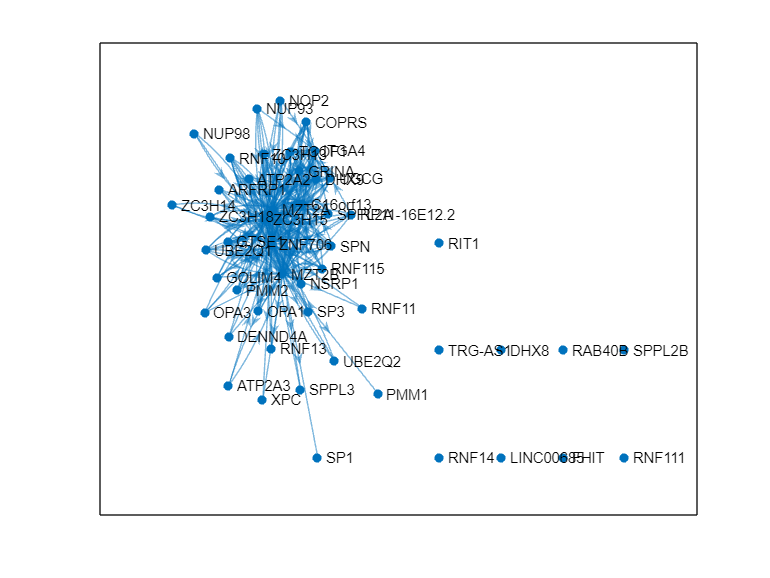

X50=X(1:50,:);
genelist50=genelist(1:50);
A=sc_pcnet(X50);

% Plot constructed network
%
A=A.*(abs(A)>quantile(abs(A(:)),0.9));
G=digraph(A,genelist50);
LWidths=abs(5*G.Edges.Weight/max(G.Edges.Weight));
LWidths(LWidths==0)=1e-5;
figure;
plot(G,'LineWidth',LWidths);

p.MarkerSize = 7;
p.Marker = 's';
p.NodeColor = 'r';

## Using GENIE3 method

X20=X(1:20,:);
genelist20=genelist(1:20);
A=run.ml_GENIE3(X20);

Tree method: RF
K: sqrt
Number of trees: 1000

Gene 1/20...
Table prediction_values = 1567000 x 1
Gene 2/20...
Table prediction_values = 1567000 x 1
Gene 3/20...
Table prediction_values = 1567000 x 1
Gene 4/20...
Table prediction_values = 1567000 x 1
Gene 5/20...
Table prediction_values = 1567000 x 1
Gene 6/20...
Table prediction_values = 1567000 x 1
Gene 7/20...
Table prediction_values = 1567000 x 1
Gene 8/20...
Table prediction_values = 1567000 x 1
Gene 9/20...
Table prediction_values = 1567000 x 1
Gene 10/20...
Table prediction_values = 1567000 x 1
Gene 11/20...
Table prediction_values = 1567000 x 1
Gene 12/20...
Table prediction_values = 1567000 x 1
Gene 13/20...
Table prediction_values = 1567000 x 1
Gene 14/20...
Table prediction_values = 1567000 x 1
Gene 15/20...
Table prediction_values = 1567000 x 1
Gene 16/20...
Table prediction_values = 1567000 x 1
Gene 17/20...
Table prediction_values = 1567000 x 1
Gene 18/20...
Table prediction_values = 1567000 x 1
Gene 19/20...
Table predic

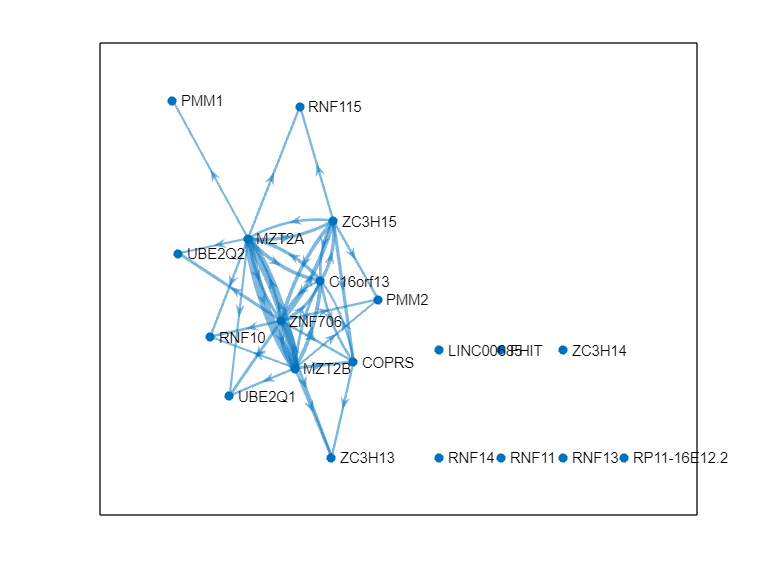


% Plot constructed network
%
A=A.*(abs(A)>quantile(abs(A(:)),0.9));
G=digraph(A,genelist20);
LWidths=abs(5*G.Edges.Weight/max(G.Edges.Weight));
LWidths(LWidths==0)=1e-5;
figure;
plot(G,'LineWidth',LWidths);

p.MarkerSize = 7;
p.Marker = 's';
p.NodeColor = 'r';

## The End